clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[-0.090;2.949;1.348];
u31=[0.717;-0.541;0.439];
r2=[8.150;2.949;1.348];
u32=[0.717;-0.541;0.439];
r3=[4.030;7.346;6.812];
u33=[0.717;0.541;-0.439];
r4=[4.210;-2.949;5.428];
u34=[-0.717;0.541;0.439];
r5=[4.030;7.346;-1.348];
u35=[0.717;0.541;-0.439];
r6=[-4.030;-2.949;5.428];
u36=[-0.717;0.541;0.439];
r7=[-0.090;2.949;9.508];
u37=[0.717;-0.541;0.439];


x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];
x8=[];
y8=[];
x9=[];
y9=[];
x10=[];
y10=[];
x11=[];
y11=[];

hold on 
axis([0 15 0 15]);
for R1=10:-0.3:4 %离心率
    R3=3;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =    10.0000    3.0500    1.0184


ans =     9.7000    3.0500    1.0238


ans =     9.4000    3.0500    1.0296


ans =     9.1000    3.1000    1.0061


ans =     8.8000    3.1000    1.0131


ans =     8.5000    3.1000    1.0209


ans =     8.2000    3.1500    1.0010


ans =     7.9000    3.1500    1.0106


ans =     7.6000    3.1500    1.0214


ans =     7.3000    3.2000    1.0062


ans =     7.0000    3.2000    1.0199


ans =     6.7000    3.2500    1.0094


ans =     6.4000    3.3000    1.0023


ans =     6.1000    3.3000    1.0226


ans =     5.8000    3.3500    1.0225


ans =     5.5000    3.4500    1.0056


ans =     5.2000    3.5000    1.0173


ans =     4.9000    3.6000    1.0168


ans =     4.6000    3.7500    1.0103


ans =     4.3000    3.9500    1.0054


ans =     4.0000    4.2000    1.0102



for R3=4:0.3:13 %离心率
    R1=3;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     4.2500    4.0000    1.0020


ans =     3.9500    4.3000    1.0006


ans =     3.7000    4.6000    1.0149


ans =     3.5500    4.9000    1.0179


ans =     3.4500    5.2000    1.0156


ans =     3.4000    5.5000    1.0019


ans =     3.3000    5.8000    1.0167


ans =     3.2500    6.1000    1.0153


ans =     3.2000    6.4000    1.0184


ans =     3.1500    6.7000    1.0255


ans =     3.1500    7.0000    1.0092


ans =     3.1000    7.3000    1.0219


ans =     3.1000    7.6000    1.0092


ans =     3.0500    7.9000    1.0263


ans =     3.0500    8.2000    1.0163


ans =     3.0500    8.5000    1.0072


ans =     3.0000    8.8000    1.0289


ans =     3.0000    9.1000    1.0216


ans =     3.0000    9.4000    1.0150


ans =     3.0000    9.7000    1.0090


ans =     3.0000   10.0000    1.0035


ans =     2.9500   10.3000    1.0298


ans =     2.9500   10.6000    1.0252


ans =     2.9500   10.9000    1.0210


ans =     2.9500   11.2000    1.0171


ans =     2.9500   11.5000    1.0135


ans =     2.9500   11.8000    1.0102


ans =     2.9500   12.1000    1.0072


ans =     2.9500   12.4000    1.0043


ans = 1×3
    2.9500   12.7000    1.0017


ans = 1×3
    2.9000   13.0000    1.0321



for R3=1:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans = 1×3
    4.5000    1.0000    1.0172


ans = 1×3
    4.5000    1.3000    1.0037


ans = 1×3
    4.4500    1.6000    1.0090


ans = 1×3
    4.4000    1.9000    1.0120


ans = 1×3
    4.3500    2.2000    1.0132


ans = 1×3
    4.3000    2.5000    1.0130


ans = 1×3
    4.2500    2.8000    1.0122


ans = 1×3
    4.2000    3.1000    1.0112


ans = 1×3
    4.1500    3.4000    1.0105


ans = 1×3
    4.1000    3.7000    1.0106


ans = 1×3
    4.0500    4.0000    1.0117


ans = 1×3
    4.0000    4.3000    1.0142


ans = 1×3
    3.9500    4.6000    1.0180


ans = 1×3
    3.9500    4.9000    1.0011


ans = 1×3
    3.9000    5.2000    1.0078


ans = 1×3
    3.8500    5.5000    1.0161


ans = 1×3
    3.8500    5.8000    1.0029


ans = 1×3
    3.8000    6.1000    1.0139


ans = 1×3
    3.8000    6.4000    1.0028


ans = 1×3
    3.7500    6.7000    1.0164


ans = 1×3
    3.7500    7.0000    1.0070


ans = 1×3
    3.7000    7.3000    1.0229


ans = 1×3
    3.7000    7.6000    1.0151


ans = 1×3
    3.7000    7.9000    1.0079


ans = 1×3
    3.7000    8.2000    1.0013


ans = 1×3
    3.6500    8.5000    1.0204


ans = 1×3
    3.6500    8.8000    1.0148


ans = 1×3
    3.6500    9.1000    1.0096


ans = 1×3
    3.6500    9.4000    1.0049


ans = 1×3
    3.6500    9.7000    1.0005


ans = 1×3
    3.6000   10.0000    1.0225


ans = 1×3
    3.6000   10.3000    1.0187


ans = 1×3
    3.6000   10.6000    1.0152


ans = 1×3
    3.6000   10.9000    1.0119


ans = 1×3
    3.6000   11.2000    1.0089


ans = 1×3
    3.6000   11.5000    1.0061


ans = 1×3
    3.6000   11.8000    1.0034


ans = 1×3
    3.6000   12.1000    1.0010


ans = 1×3
    3.5500   12.4000    1.0257


ans = 1×3
    3.5500   12.7000    1.0235


ans = 1×3
    3.5500   13.0000    1.0215



for R3=13:-0.3:6 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
    1.2000   13.0000    1.0107


ans = 1×3
    1.2000   12.7000    1.0219


ans = 1×3
    1.2000   12.4000    1.0338


ans = 1×3
    1.2000   12.1000    1.0467


ans = 1×3
    1.2000   11.8000    1.0606


ans = 1×3
    1.2500   11.5000    1.0149


ans = 1×3
    1.2500   11.2000    1.0313


ans = 1×3
    1.2500   10.9000    1.0491


ans = 1×3
    1.3000   10.6000    1.0147


ans = 1×3
    1.3000   10.3000    1.0359


ans = 1×3
    1.3500   10.0000    1.0112


ans = 1×3
    1.3500    9.7000    1.0365


ans = 1×3
    1.4000    9.4000    1.0213


ans = 1×3
    1.4500    9.1000    1.0129


ans = 1×3
    1.5000    8.8000    1.0106


ans = 1×3
    1.5500    8.5000    1.0140


ans = 1×3
    1.6000    8.2000    1.0226


ans = 1×3
    1.7000    7.9000    1.0091


ans = 1×3
    1.8000    7.6000    1.0037


ans = 1×3
    1.9000    7.3000    1.0046


ans = 1×3
    2.0000    7.0000    1.0106


ans = 1×3
    2.1500    6.7000    1.0012


ans = 1×3
    2.2500    6.4000    1.0164


ans = 1×3
    2.4000    6.1000    1.0172



for R1=3:0.3:9 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
    3.0000    5.2000    1.0097


ans = 1×3
    3.3000    4.8500    1.0109


ans = 1×3
    3.6000    4.6000    1.0026


ans = 1×3
    3.9000    4.3500    1.0064


ans = 1×3
    4.2000    4.1500    1.0055


ans = 1×3
    4.5000    3.9500    1.0113


ans = 1×3
    4.8000    3.8000    1.0059


ans = 1×3
    5.1000    3.6500    1.0028


ans = 1×3
    5.4000    3.5000    1.0007


ans = 1×3
    5.7000    3.3000    1.0146


ans = 1×3
    6.0000    3.1500    1.0116


ans = 1×3
    6.3000    3.0000    1.0073


ans = 1×3
    6.6000    2.8500    1.0012


ans = 1×3
    6.9000    2.6500    1.0078


ans = 1×3
    7.2000    2.4500    1.0114


ans = 1×3
    7.5000    2.2500    1.0119


ans = 1×3
    7.8000    2.0500    1.0093


ans = 1×3
    8.1000    1.8500    1.0039


ans = 1×3
    8.4000    1.6000    1.0082


ans = 1×3
    8.7000    1.3500    1.0093


ans = 1×3
    9.0000    1.1000    1.0077



for R3=1:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];   
end

ans = 1×3
    5.5000    1.0000    1.0099


ans = 1×3
    5.2000    1.3000    1.0117


ans = 1×3
    4.9000    1.6000    1.0138


ans = 1×3
    4.6500    1.9000    1.0007


ans = 1×3
    4.3500    2.2000    1.0036


ans = 1×3
    4.0500    2.5000    1.0069


ans = 1×3
    3.7500    2.8000    1.0104


ans = 1×3
    3.4500    3.1000    1.0138


ans = 1×3
    3.2000    3.4000    1.0014


ans = 1×3
    2.9000    3.7000    1.0042


ans = 1×3
    2.6000    4.0000    1.0069


ans = 1×3
    2.3000    4.3000    1.0099


ans = 1×3
    2.0000    4.6000    1.0137


ans = 1×3
    1.7500    4.9000    1.0031


ans = 1×3
    1.4500    5.2000    1.0111


ans = 1×3
    1.2000    5.5000    1.0070


ans = 1×3
    0.9500    5.8000    1.0109


ans = 1×3
    0.7500    6.1000    1.0117


ans = 1×3
    0.6000    6.4000    1.0234


ans = 1×3
    0.5500    6.7000    1.0019


ans = 1×3
    0.5000    7.0000    1.0115


ans = 1×3
    0.4500    7.3000    1.0623


ans = 1×3
    0.4500    7.6000    1.0218


ans = 1×3
    0.4000    7.9000    1.1348


ans = 1×3
    0.4000    8.2000    1.1048


ans = 1×3
    0.4000    8.5000    1.0783


ans = 1×3
    0.4000    8.8000    1.0547


ans = 1×3
    0.4000    9.1000    1.0336


ans = 1×3
    0.4000    9.4000    1.0147


ans = 1×3
    0.3500    9.7000    1.2237


ans = 1×3
    0.3500   10.0000    1.2087





for R3=2:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r7,R1,R3,u31,u37);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    [R1,R3,miu2]
    x6=[x6,R1];
    y6=[y6,R3];   
end

ans = 1×3
    8.1500    2.0000    1.0014


ans = 1×3
    5.8000    2.3000    1.0052


ans = 1×3
    5.0500    2.6000    1.0013


ans = 1×3
    4.6500    2.9000    1.0029


ans = 1×3
    4.4000    3.2000    1.0074


ans = 1×3
    4.2500    3.5000    1.0059


ans = 1×3
    4.1500    3.8000    1.0024


ans = 1×3
    4.0500    4.1000    1.0101


ans = 1×3
    4.0000    4.4000    1.0056


ans = 1×3
    3.9500    4.7000    1.0065


ans = 1×3
    3.9000    5.0000    1.0118


ans = 1×3
    3.8500    5.3000    1.0208


ans = 1×3
    3.8500    5.6000    1.0089


ans = 1×3
    3.8000    5.9000    1.0228


ans = 1×3
    3.8000    6.2000    1.0141


ans = 1×3
    3.8000    6.5000    1.0065


ans = 1×3
    3.7500    6.8000    1.0250


ans = 1×3
    3.7500    7.1000    1.0192


ans = 1×3
    3.7500    7.4000    1.0142


ans = 1×3
    3.7500    7.7000    1.0097


ans = 1×3
    3.7500    8.0000    1.0057


ans = 1×3
    3.7500    8.3000    1.0021


ans = 1×3
    3.7000    8.6000    1.0250


ans = 1×3
    3.7000    8.9000    1.0221


ans = 1×3
    3.7000    9.2000    1.0195


ans = 1×3
    3.7000    9.5000    1.0171


ans = 1×3
    3.7000    9.8000    1.0150


ans = 1×3
    3.7000   10.1000    1.0130


ans = 1×3
    3.7000   10.4000    1.0112


ans = 1×3
    3.7000   10.7000    1.0096


ans = 1×3
    3.7000   11.0000    1.0081


ans = 1×3
    3.7000   11.3000    1.0067


ans = 1×3
    3.7000   11.6000    1.0054


ans = 1×3
    3.7000   11.9000    1.0042


ans = 1×3
    3.7000   12.2000    1.0031


ans = 1×3
    3.7000   12.5000    1.0021


ans = 1×3
    3.7000   12.8000    1.0011


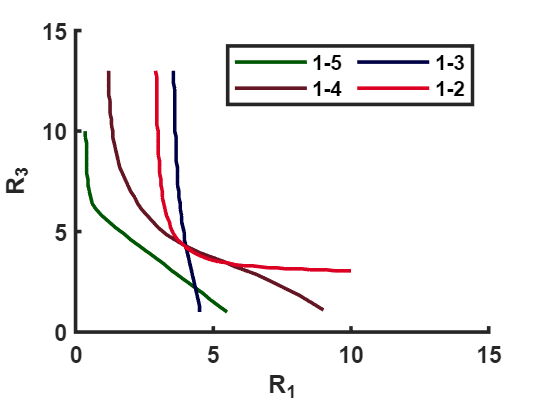


plot(x5,y5,'color',[200, 50, 0]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-6');


plot(x4,y4,'color',[0, 87, 3]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-5');

plot(x3,y3,'color',[100, 22, 35]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-4');

plot(x2,y2,'color',[0, 0, 69]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-3');

plot(x1,y1,'color',[221, 0, 35]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-2');








set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast','NumColumns',2);
hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end

